% Load the file '2021_6_19_23_59_24.mat'
data = load('2021_6_19_23_59_24.mat').out_data;

% Extract the year, month, day, hour, minute, and second data from the file
year = data(:,1);
month = data(:,2);
day = data(:,3);
hour = data(:,4);
minute = data(:,5);
second = data(:,6);

% Convert the year, month, day, hour, minute, and second data to a datetime array
time = datetime(year, month, day, hour, minute, second);

% Convert the trigger time to a datetime
trigger_time = datetime('2021-06-19T23:59:24.915', 'InputFormat', 'uuuu-MM-dd''T''HH:mm:ss.SSS');

% Calculate the time difference between each time in the file and the trigger time
time_diff = seconds(time - trigger_time);

% Add the time difference as a new column in the data array
data = [data, time_diff];


% Set the binsize to 64 ms
binsize = 64e-3; % 64 ms in seconds

% Set the lower and upper limits for the time differences
lower_limit = 0.5; % 0.5 seconds
upper_limit = 5; % 5 seconds

% Create the bins for the histogram
bins = lower_limit:binsize:upper_limit;

% Use the histcounts function to create the light curve
[counts, ~] = histcounts(time_diff, bins);


% Extract the center of the bins
bin_centers = (bins(1:end-1) + bins(2:end)) / 2;

% Plot the light curve using the bar function
bar(bin_centers, counts);

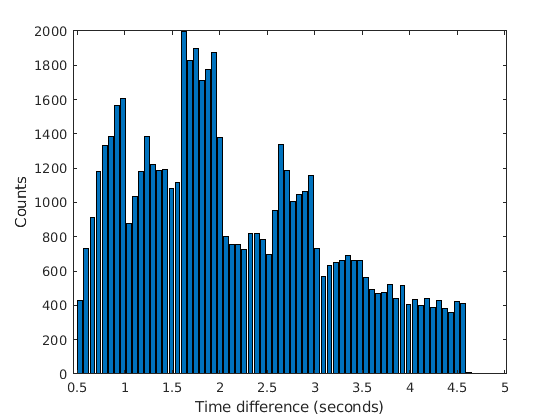


% Add axis labels
xlabel('Time difference (seconds)');
ylabel('Counts');